**Definition du systeme**

Nous avons un système avec trois fréquences de coupure. Définissons G(s) la fonction de transfert du  moteur, F(s) la fonction de transfert du filtre et C(s) la fonction de transfert du correcteur.

clear all;
close all; 
clc;
s=tf('s');

G(s):

L=0.002

L = 0.0020

R=1

R = 1

t1= L/R

t1 = 0.0020

Kg=1/R

Kg = 1

Km=48

Km = 48

G=Kg*Km/(1+t1*s)

G =
 
      48
  -----------
  0.002 s + 1
 
Continuous-time transfer function.



F(s)

t2= 7.43*10^-5

t2 = 7.4300e-05

t3= 4.84*10^-6

t3 = 4.8400e-06

K_capteur=0.10416

K_capteur = 0.1042

Kf=1.4

Kf = 1.4000

F=K_capteur*Kf/((1+t2*s)*(1+t3*s))

F =
 
              0.1458
  -------------------------------
  3.596e-10 s^2 + 7.914e-05 s + 1
 
Continuous-time transfer function.



C(s) [ti est la constante d'integration et K le gain du PI]

K=Kg*Km*K_capteur*Kf

K = 6.9996

ti=K/(800*pi)

ti = 0.0028

C=(t1*s+1)/(ti*s)

C =
 
  0.002 s + 1
  -----------
  0.002785 s
 
Continuous-time transfer function.



Tracé du diagramme de Bode en boucle ouverte afin de determiner K pour avoir une fréquence de coupure entre 300 et 500Hz

FTBO=bodeplot(C*G*F)


FTBO =

	resppack.bodeplot



option=getoptions(FTBO)

option =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: 0
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
      

option.FreqUnits='Hz'

option =

                   FreqUnits: 'Hz'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: 0
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
         

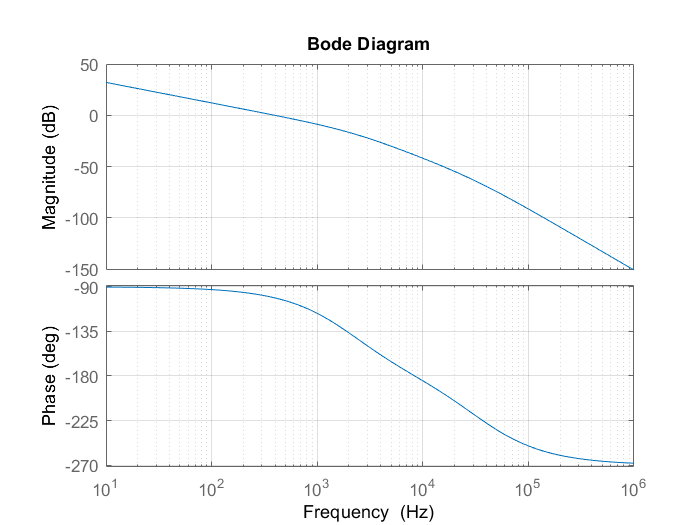

setoptions(FTBO,option)
grid on

Il ne reste qu'a faire la simulation en boucle fermée de notre système corrigé. 

H=C*G*F

H =
 
                         0.014 s + 7
  ---------------------------------------------------------
  2.003e-15 s^4 + 4.418e-10 s^3 + 5.79e-06 s^2 + 0.002785 s
 
Continuous-time transfer function.



FTBF=bodeplot(H/(1+H))


FTBF =

	resppack.bodeplot



option=getoptions(FTBF)

option =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: 0
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
      

option.FreqUnits='Hz'

option =

                   FreqUnits: 'Hz'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: 0
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
         

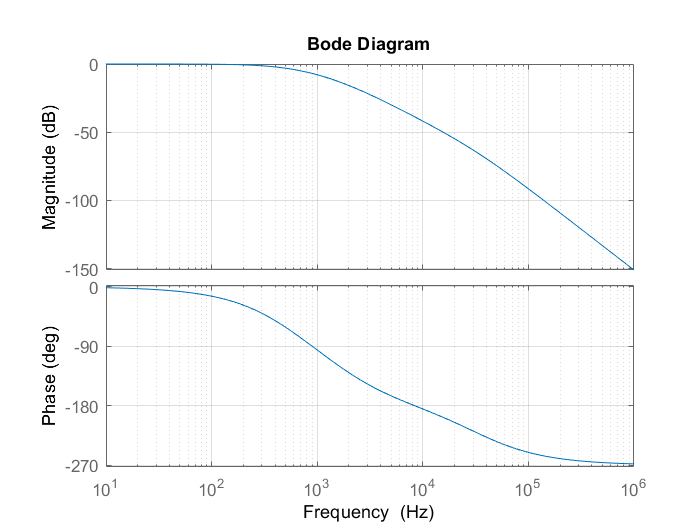

setoptions(FTBF,option)
grid on

Nous réalisons un schéma simulink du système et nous récuperons les valeurs. Nous avons ajouté un saturateur à la sortie du correcteur adin d'éviter des valeurs de rapport cyclique (alpha) supérieures à [-50%,50%]. Voici les résultats trouvés:

simout=sim('BE_Trotinette.slx')

sim = 'BE_Trotinette.slx'

x1 = simout.get('x1');
x2 = simout.get('x2');